# Deep Learning and Simulation for the Estimation of Red Blood Cell Flux With Optical Coherence Tomography

This script demonstrates how to load Optical Coherence Tomography (OCT) time-traces and a pre-trained Convolutional Neural Network (CNN) to estimate Red Blood Cell (RBC) flux and its associated uncertainty. The method is based on the findings from the paper: *Stefan S, Kim A, Marchand PJ, Lesage F and Lee J (2022) Deep Learning and Simulation for the Estimation of Red Blood Cell Flux With Optical Coherence Tomography. Front. Neurosci. 16:835773. doi: 10.3389/fnins.2022.835773*

The script will:

- Load the necessary data (including time-traces `p` and ground truth `tpm_peak` from `OCT_timetraces.mat`) and the pre-trained network.

- Prepare the data and use the network to predict RBC flux.

- Extract the flux estimates and their uncertainties.

- Optionally, visualize the estimated flux against the ground truth values.

## Prerequisites

Before running this script, ensure you have:

- MATLAB installed (Live Editor is available in R2016a or later).

- The following `.mat` files available in your MATLAB path or the current working directory: 

- `OCT_timetraces.mat`: This file should contain a variable `p` with the OCT time-series data (512 time points per trace) and a variable `tpm_peak` with the ground truth peak counts.

- `net_flux.mat`: This file should contain the pre-trained CNN model.

To obtain OCT time-traces from raw microangiogram data, you can use the tools available at: [https://github.com/sstefan01/OCTA_microangiogram_properties](https://github.com/sstefan01/OCTA_microangiogram_properties) 

## Step 1: Load Data and Pre-trained Network

First, we load the `OCT_timetraces.mat` file, which contains both the OCT signals (`p`) and the ground truth (`tpm_peak`). We also load the pre-trained CNN model.

% Load the OCT time-series data and ground truth
disp('Loading OCT time-traces and ground truth (OCT_timetraces.mat)...');
try
    loaded_data_p = load('OCT_timetraces.mat');
    if isfield(loaded_data_p, 'p') && isfield(loaded_data_p, 'tpm_peak')
        p = loaded_data_p.p;
        tpm_peak = loaded_data_p.tpm_peak;

Loading OCT time-traces and ground truth (OCT_timetraces.mat)...


        disp('OCT time-traces (p) and ground truth (tpm_peak) loaded.');
    else
        error('OCT_timetraces.mat must contain variables named ''p'' and ''tpm_peak''.');
    end
catch ME
    disp('Error loading OCT_timetraces.mat. Please ensure the file exists and contains ''p'' and ''tpm_peak''.');
    disp(ME.message);
    return; % Stop script if data isn't loaded correctly
end

% Load the pre-trained neural network
disp('Loading pre-trained network (net_flux.mat)...');
try
    loaded_data_net = load('net_flux.mat');

OCT time-traces (p) and ground truth (tpm_peak) loaded.


    if isfield(loaded_data_net, 'net_flux')
        net_flux = loaded_data_net.net_flux;
    elseif isfield(loaded_data_net, 'net') % Alternate common name for network variable

Loading pre-trained network (net_flux.mat)...


        net_flux = loaded_data_net.net;
    else
        % If only one variable in the file, assume it's the network
        fields_net = fieldnames(loaded_data_net);
        if numel(fields_net) == 1
            net_flux = loaded_data_net.(fields_net{1});
        else
            error('Could not automatically identify the network variable in net_flux.mat. Expected ''net_flux'' or ''net''.');
        end
    end
    disp('Pre-trained network loaded.');
catch ME
    disp('Error loading net_flux.mat. Please ensure the file exists and is in the path.');
    disp(ME.message);
    return; % Stop script if network isn't loaded
end

Pre-trained network loaded.


## Step 2: Prepare Data and Perform Prediction

The input data `p` needs to be reshaped to match the network's expected input format, which is typically `[height, width, channels, batch_size]`. For our 1D time-series of 512 points, this will be `[512, 1, 1, NumberOfTimeTraces]`.

disp('Reshaping data and performing network activations...');

Reshaping data and performing network activations...


% Assuming p is [TimePoints, NumberOfTraces], e.g., size(p) = [512, N]
% If p is [NumberOfTraces, TimePoints], e.g., size(p) = [N, 512], then transpose it:
% if size(p, 2) == 512 && size(p, 1) ~= 512
%     p = p';
% end

if size(p, 1) ~= 512
    error('Input data `p` does not have 512 time points in its first dimension. Please check data format.');
end

num_traces = size(p, 2); % Number of time-traces to process
reshaped_p = reshape(p, 512, 1, 1, num_traces);

% Pass the data through the network to get activations from the 'regressionoutput' layer.
% This layer provides two outputs: the RBC flux estimate and its uncertainty.
oo = activations(net_flux, reshaped_p, 'regressionoutput');

% Remove singleton dimensions from the output for easier handling.
% The output 'oo' should now be [2, NumberOfTimeTraces].
oo = squeeze(oo);
disp('Network prediction complete.');

Network prediction complete.


## Step 3: Extract Results

The output `oo` from the network contains the estimated flux and its standard deviation (uncertainty).

% The first row of 'oo' contains the RBC flux estimates.
flux_estimate = oo(1, :); % Units: RBCs/second

% The second row of 'oo' contains the uncertainty (standard deviation) of the estimates.
flux_std = oo(2, :); % Units: RBCs/second

disp('Flux estimation and uncertainty extracted.');

Flux estimation and uncertainty extracted.


disp(['Number of traces processed: ', num2str(num_traces)]);

Number of traces processed: 1207


if num_traces > 0
    disp(['Example estimated flux (first trace): ', num2str(flux_estimate(1)), ' RBCs/s']);
    disp(['Example flux uncertainty (first trace): ', num2str(flux_std(1)), ' RBCs/s']);
end

Example estimated flux (first trace): 85.2727 RBCs/s


Example flux uncertainty (first trace): 20.5945 RBCs/s


## Step 4: Visualize Results

This section plots the estimated RBC flux against the ground truth flux. The `tpm_peak` variable (loaded from `OCT_timetraces.mat`) contains the true peak counts from TPEF for each time-trace. The acquisition time (0.7680 seconds, corresponding to 512 points at 1.5ms) is used to convert these peak counts into a flux value (RBCs/second).

disp('Plotting validation graph using tpm_peak from OCT_timetraces.mat...');

Plotting validation graph using tpm_peak from OCT_timetraces.mat...


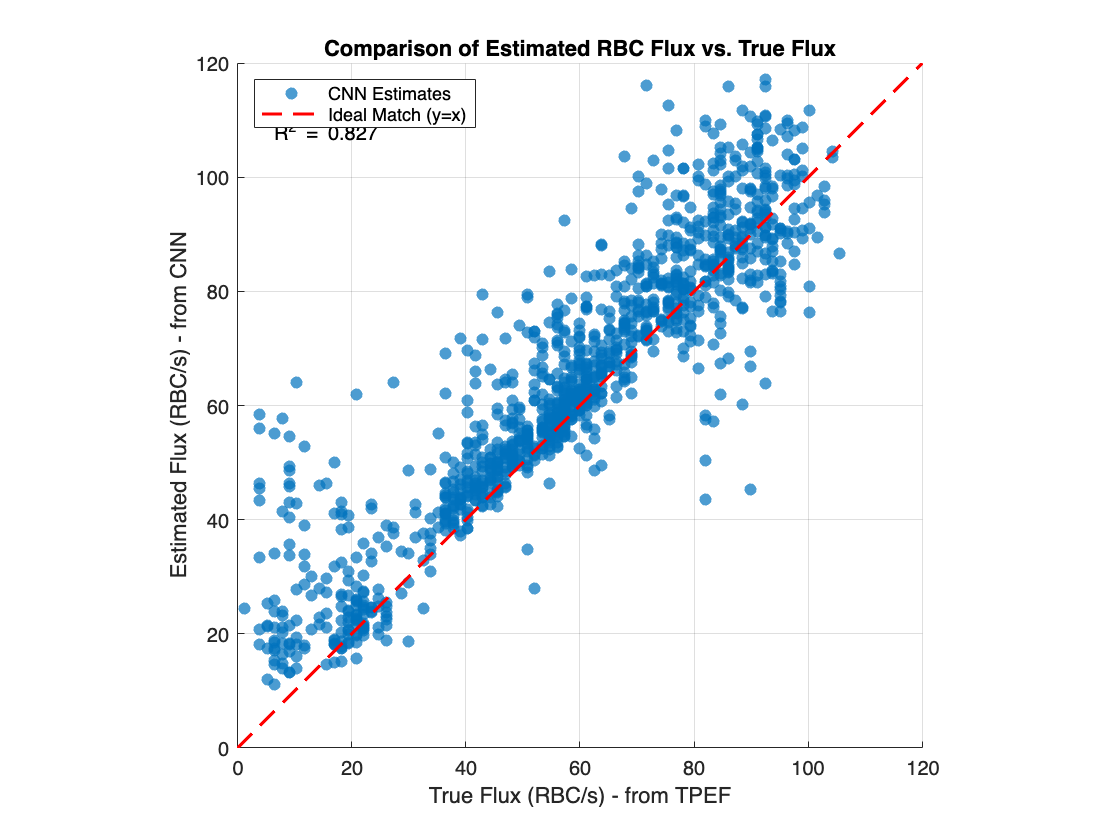


if exist('tpm_peak', 'var') && ~isempty(tpm_peak)
    if length(tpm_peak) ~= num_traces
        warning('Length of tpm_peak does not match the number of processed traces. Plot may be incorrect or fail.');
        % Attempt to reshape tpm_peak if it's a row vector and p had traces as columns (or vice versa)
        if isrow(tpm_peak) && num_traces == length(tpm_peak)
             % tpm_peak is already fine if num_traces reflects columns of p
        elseif iscolumn(tpm_peak) && num_traces == length(tpm_peak)
            disp('Reshaping tpm_peak to be a row vector for consistency.');
            tpm_peak = tpm_peak';
        else
             error('Cannot reconcile dimensions of tpm_peak with the number of traces.');
        end
    end
    
    ground_truth_flux = tpm_peak / 0.7680; % Convert peak counts to flux (RBCs/s)

    figure;
    scatter(ground_truth_flux, flux_estimate, 36, 'filled', 'MarkerFaceAlpha', 0.7); % 36 is marker size
    hold on;
    % Plot the y=x line for reference (ideal match)
    plot_limits = [min([0, ground_truth_flux, flux_estimate]), max([120, ground_truth_flux, flux_estimate])];
    plot(plot_limits, plot_limits, 'r--', 'LineWidth', 1.5);
    hold off;

    xlabel('True Flux (RBC/s) - from TPEF');
    ylabel('Estimated Flux (RBC/s) - from CNN');
    title('Comparison of Estimated RBC Flux vs. True Flux');
    legend('CNN Estimates', 'Ideal Match (y=x)', 'Location', 'northwest');
    axis equal; % Ensures 1:1 aspect ratio
    xlim(plot_limits);
    ylim(plot_limits);
    grid on;
    
    % Display R-squared value
    if length(ground_truth_flux) == length(flux_estimate) && length(ground_truth_flux) > 1
        R = corrcoef(ground_truth_flux(~isnan(ground_truth_flux) & ~isnan(flux_estimate)), flux_estimate(~isnan(ground_truth_flux) & ~isnan(flux_estimate)));
        if numel(R) >= 2
            R2 = R(1,2)^2;
            text(plot_limits(1) + (plot_limits(2)-plot_limits(1))*0.05, ...
                 plot_limits(2) - (plot_limits(2)-plot_limits(1))*0.1, ...
                 ['R^2 = ', num2str(R2, '%.3f')], 'FontSize', 10);
        else
            disp('Not enough data points to calculate R-squared after removing NaNs.');
        end
    else
        disp('Ground truth and estimated flux vectors have different lengths or are too short; R-squared not calculated.');
    end
else
    disp('Ground truth variable ''tpm_peak'' not found or is empty from OCT_timetraces.mat. Skipping validation plot.');
end